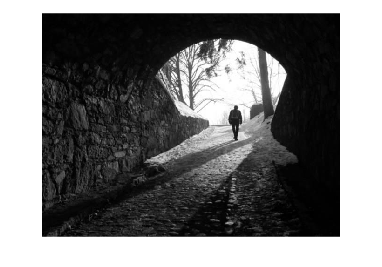

% Load image
I = truecolorload('./images/3before.png');
I = I(:,:,1);
imshow(I);

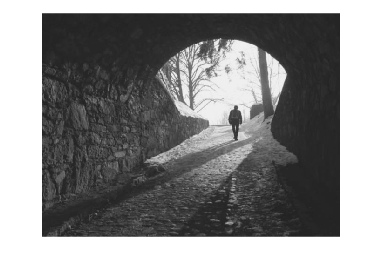


[m, n] = size(I, 1, 2);

% Convert to DCT
J = dct2(I);

% imshow(log(abs(J)),[]),
% colormap(gca,jet(64)), colorbar

% 'Contrast'
CR = 0.8;
mask = false;
mask = padarray(mask, [m-1 n-1], true, 'post');
J(mask) = J(mask) .* CR;

% 'Brightness'
BR = 1.5;
J(1, 1) = J(1, 1) * BR;


% Revert to Spatial
O = idct2(J);
imshow(O, [0 256]);

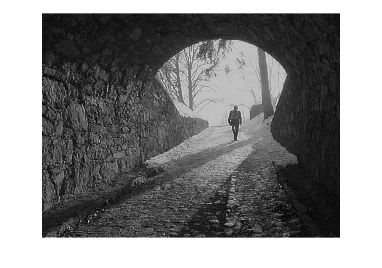


% Compare with original
I = truecolorload('./images/3after.png');
imshow(I);